## armdac to fc routine @ all gains

stable version last updated on 05 june 2018 

clearvars;
leg     = 'Threshold vs. ArmDac';
x_label = 'ArmDac';
y_label = 'Threshold(fC)';
%load Arming_fit.mat;
VFAT3_NUMBER = 'vfat3#45';
Peaking_time = "45"; % 15 25 36 45 
Pre_Gain =  "HG"  ;% LG MG HG  
start_chan = 0 ;stop_chan = 127 ;step_chan = 1 ;
Latency = uint16(0);
LV1As   = uint16(1000);
D1 = uint16(5) ;D2 = uint16(400) ;DELAY = uint8(1);
calpulse = uint8(1);
 
%start_fc = -2.0 ;
%stop_fc = 20.0 ;

num_of_channels = ( (stop_chan - start_chan)/step_chan)+1;

## connect hard reset chip

sync_chip();

received  3a , sync OK 


## Adjust IREF

AdjustIref();

IREF = 23 , adc = 101.13 


## Cal_dac to fC

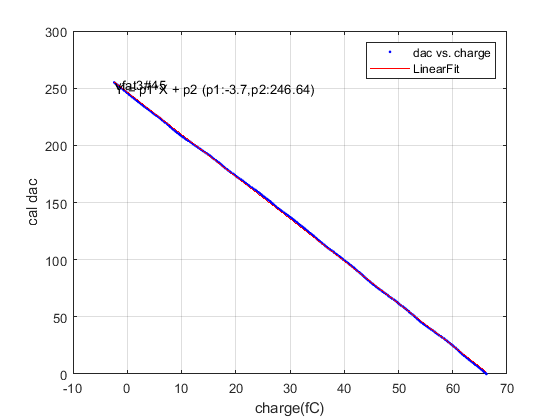

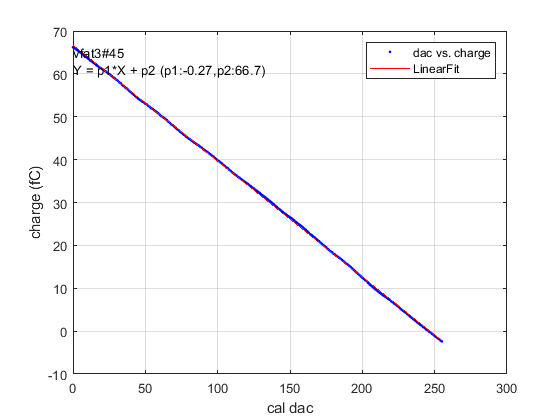

start_fc = 0.0 ;
stop_fc = 6.0 ;
[Lfit_caldac,Lfit_charge,step_fc]= caldac_to_fC(VFAT3_NUMBER);

fc_arr = double(start_fc:step_fc:stop_fc);
fc_size = size(fc_arr,2); 
dac = uint8(round(Lfit_caldac(fc_arr)));

## front end settings

Pre_Gain =  "HG"  ;% LG MG HG  
set_preamp(Peaking_time,Pre_Gain);

11100100

## front end default configurations

front_end_default  = [202 255 9 ]';
t = tcpip('192.168.1.10',7);
fopen(t);
fwrite(t,front_end_default);
fclose(t);

## ensure all trim dacs are at zero

for i=0 : 127
    write_register(i,0);
end

%% run arm dac calibration @ LG,45
start_fc = 0.0 ;
stop_fc = 30.0 ;
fc_arr = double(start_fc:step_fc:stop_fc);
fc_size = size(fc_arr,2); 
dac = uint8(round(Lfit_caldac(fc_arr)));

        Pre_Gain = "LG";
       set_preamp(Peaking_time,Pre_Gain);

11110011

i=1;
arm_dac = 25;
while(arm_dac<=75)
    arm_dac_arr_LG(i)= arm_dac;
[~,~,~,M_O_mean_Th,~,~,~] = scurve_all_channel(start_chan,stop_chan,step_chan,Latency,LV1As,arm_dac,D1,D2,DELAY,start_fc,stop_fc,fc_arr,dac,calpulse);
%scurve_Multichannels  It performs scurve for more than one channel
Threshold_arr_LG(i) = M_O_mean_Th;
fprintf('\n\r arm_dac = %d, Threshold_LG = %f, Pre_Gain = %s',arm_dac_arr_LG(i),Threshold_arr_LG(i),"LG");
i = i+1;
arm_dac=arm_dac+25;
end



 arm_dac = 25, Threshold_LG = 6.869224, Pre_Gain = LG

 arm_dac = 50, Threshold_LG = 13.096542, Pre_Gain = LG

 arm_dac = 75, Threshold_LG = 19.767893, Pre_Gain = LG

## linear fitting

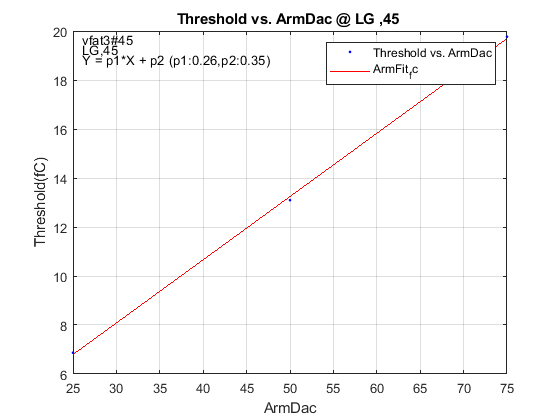

[Arming_fit_LG,~] = ArmFit_fc(arm_dac_arr_LG,Threshold_arr_LG,leg,x_label,y_label,VFAT3_NUMBER,"LG",Peaking_time);
title('Threshold vs. ArmDac @ LG ,45 ');

start_fc = 0.0 ;
stop_fc = 20.0 ;
fc_arr = double(start_fc:step_fc:stop_fc);
fc_size = size(fc_arr,2); 
dac = uint8(round(Lfit_caldac(fc_arr)));
        Pre_Gain = "MG";
       set_preamp(Peaking_time,Pre_Gain);

11101001

i=1;
arm_dac = 25;
while(arm_dac<=75)
    arm_dac_arr_MG(i)= arm_dac;
[~,~,~,M_O_mean_Th,~,~,~] = scurve_all_channel(start_chan,stop_chan,step_chan,Latency,LV1As,arm_dac,D1,D2,DELAY,start_fc,stop_fc,fc_arr,dac,calpulse);
%scurve_Multichannels  It performs scurve for more than one channel
Threshold_arr_MG(i) = M_O_mean_Th;
fprintf('\n\r arm_dac = %d, Threshold_MG = %f, Pre_Gain = %s',arm_dac_arr_MG(i),Threshold_arr_MG(i),"MG");
i = i+1;
arm_dac=arm_dac+25;
end



 arm_dac = 25, Threshold_MG = 3.730209, Pre_Gain = MG

 arm_dac = 50, Threshold_MG = 6.930444, Pre_Gain = MG

 arm_dac = 75, Threshold_MG = 10.617633, Pre_Gain = MG

## linear fitting

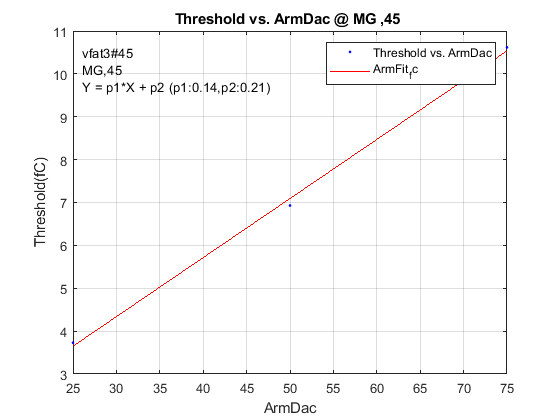

[Arming_fit_MG,~] = ArmFit_fc(arm_dac_arr_MG,Threshold_arr_MG,leg,x_label,y_label,VFAT3_NUMBER,"MG",Peaking_time);
title('Threshold vs. ArmDac @ MG ,45 ');

start_fc = 0.0 ;
stop_fc = 5.0 ;
fc_arr = double(start_fc:step_fc:stop_fc);
fc_size = size(fc_arr,2) ;
dac = uint8(round(Lfit_caldac(fc_arr)));
        Pre_Gain = "HG";
       set_preamp(Peaking_time,Pre_Gain);

11100100

i=1;
arm_dac = 25;
while(arm_dac<=100)
    arm_dac_arr_HG(i)= arm_dac;
[~,~,~,M_O_mean_Th,~,~,~] = scurve_all_channel(start_chan,stop_chan,step_chan,Latency,LV1As,arm_dac,D1,D2,DELAY,start_fc,stop_fc,fc_arr,dac,calpulse);
%scurve_Multichannels  It performs scurve for more than one channel
Threshold_arr_HG(i) = M_O_mean_Th;
fprintf('\n\r arm_dac = %d, Threshold_HG = %f, Pre_Gain = %s',arm_dac_arr_HG(i),Threshold_arr_HG(i),"HG");
i = i+1;
arm_dac=arm_dac+25;
end



 arm_dac = 25, Threshold_HG = 1.520929, Pre_Gain = HG

 arm_dac = 50, Threshold_HG = 2.646280, Pre_Gain = HG

 arm_dac = 75, Threshold_HG = 3.823506, Pre_Gain = HG

all weightts found 0 




 arm_dac = 100, Threshold_HG = 4.450246, Pre_Gain = HG

## linear fitting

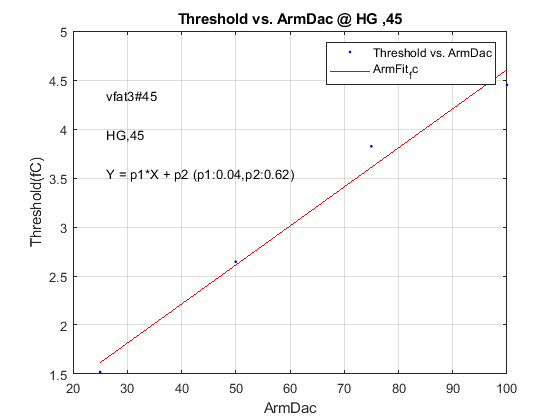

[Arming_fit_HG,~] = ArmFit_fc(arm_dac_arr_HG,Threshold_arr_HG,leg,x_label,y_label,VFAT3_NUMBER,"HG",Peaking_time);
title('Threshold vs. ArmDac @ HG ,45');

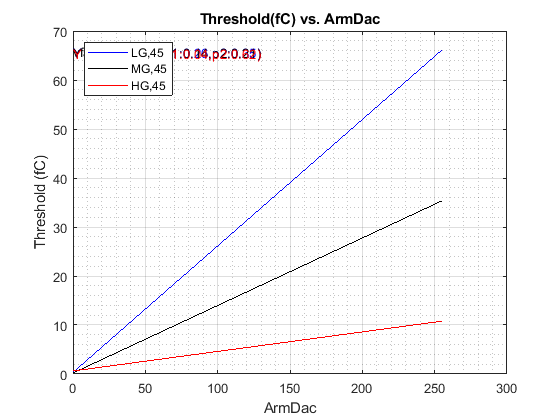

dac_common = 0:255;

Th_LG =Arming_fit_LG(dac_common); 
Th_MG= Arming_fit_MG(dac_common);
Th_HG= Arming_fit_HG(dac_common);

figure
plot(dac_common,Th_LG,'b',dac_common,Th_MG,'black',dac_common,Th_HG,'red')
grid on
grid minor
legend('LG,45','MG,45','HG,45','Location','northwest')
title 'Threshold(fC) vs. ArmDac'
xlabel 'ArmDac'
ylabel 'Threshold (fC)'
str0 = ['',VFAT3_NUMBER];
str1 = [ 'Y = p1*X + p2 (p1:',num2str(round(Arming_fit_LG.p1,2)),',','p2:',num2str(round(Arming_fit_LG.p2,2)),')'];
str2 = [ 'Y = p1*X + p2 (p1:',num2str(round(Arming_fit_MG.p1,2)),',','p2:',num2str(round(Arming_fit_MG.p2,2)),')'];
str3 = [ 'Y = p1*X + p2 (p1:',num2str(round(Arming_fit_HG.p1,2)),',','p2:',num2str(round(Arming_fit_HG.p2,2)),')'];
x0=min(dac_common);y0=max(Th_LG)- 0.3;
x1=x0 ;y1=y0 - .1;
x2=x0; y2=y1 - .1;
x3=x0; y3=y2 - .1;
text(x0,y0,str0,'color','black');
text(x1,y1,str1,'color','b');
text(x2,y2,str2,'color','black');
text(x3,y3,str3,'color','red');